% 4.读入nii图像并显示
tof_vol = spm_vol(['TOF_nii/Mag.nii.gz' ...

Compressed NIfTI files are not supported.


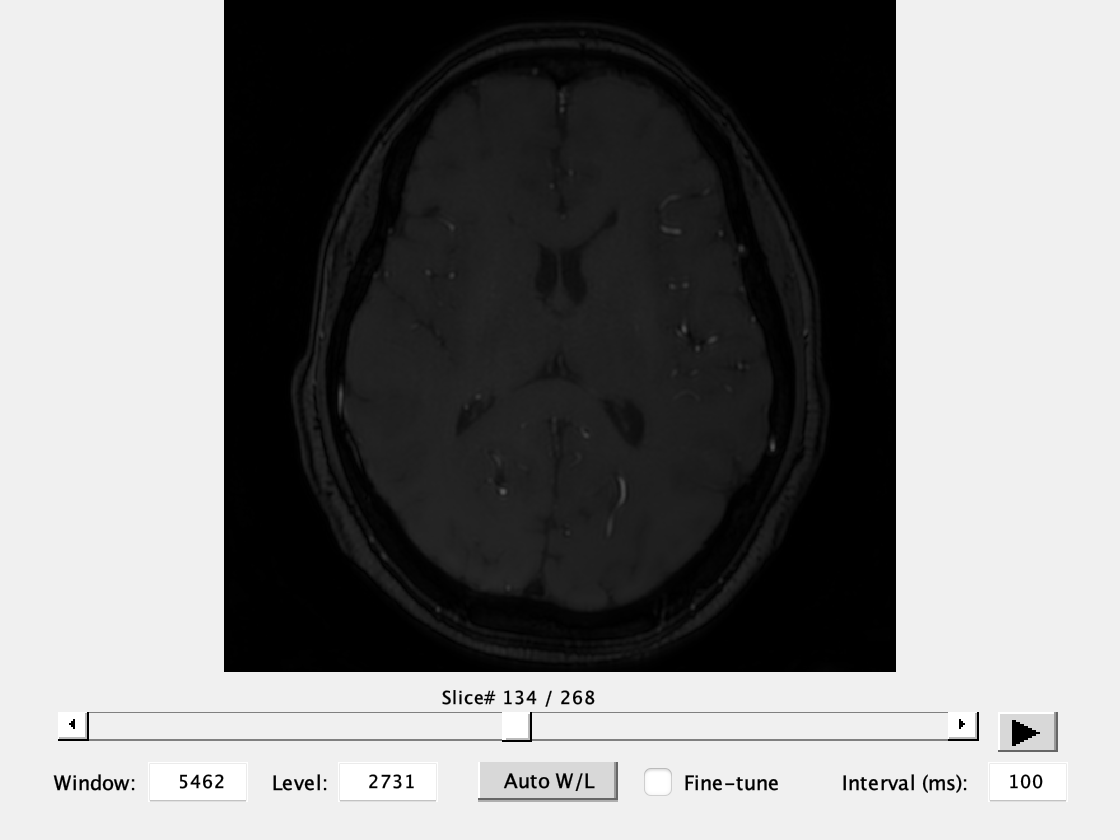

    '']);
tof = imrotate(spm_read_vols(tof_vol), 90);
figure, imshow3D(tof);

X_sag = dicomread('DSA_LVA_sag/Image (0017).dcm');
X_cor = dicomread('DSA_LVA_cor/Image (0017).dcm');
% X = dicomread('TOF_Dicom/Mag (0001).dcm');

% 5.
imshow(X_sag)

% >>imcontrast调整图像对比度

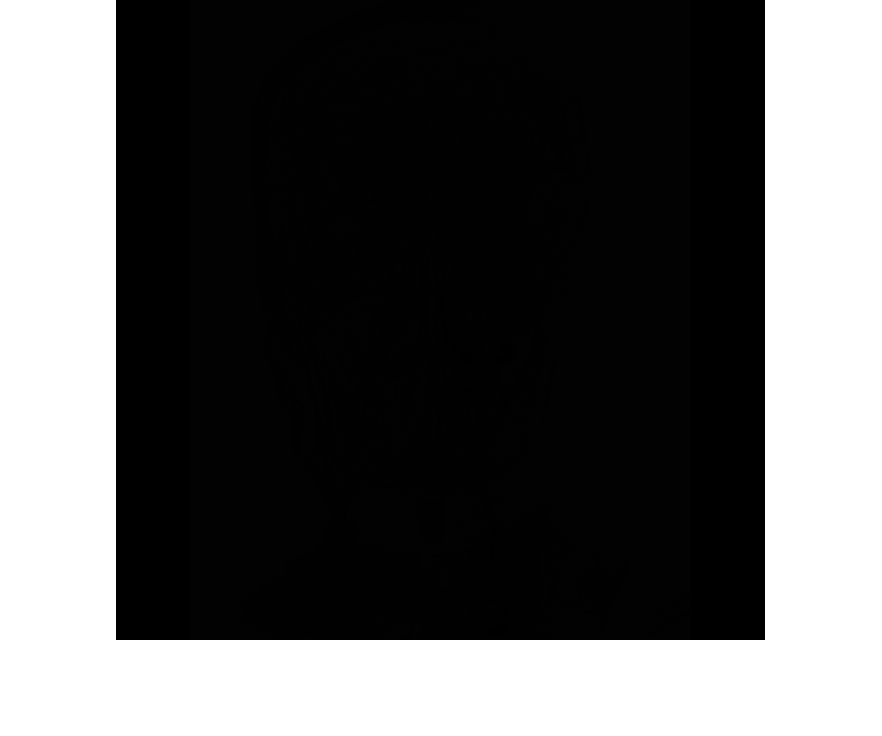

imshow(X_cor)

% 6.MIP

% 第一维最大值
tof_max_1 = max(tof, [], 1);
% 第二维最大值
tof_max_2 = max(tof, [], 2 );

mip_1 = squeeze(tof_max_1);
mip_1 = imrotate(mip_1, 90);
mip_2 = squeeze(tof_max_2);
mip_2 = fliplr(imrotate(mip_2, 90));

imshow(mip_1)

imshow(mip_2)

% 8
X_info = dicominfo('TOF_Dicom/Mag (0001).dcm')

X_info = 包含以下字段的 struct :
                                       Filename: '/Users/liujiyao/Documents/2022课程/医学图像处理/作业/2 Exercise/TOF_Dicom/Mag (0001).dcm'
                                    FileModDate: '01- 9-2022 12:52:06'
                                       FileSize: 568664
                                         Format: 'DICOM'
                                  FormatVersion: 3
                                          Width: 528
                                         Height: 528
                                       BitDepth: 12
                                      ColorType: 'grayscale'
                 FileMetaInformationGroupLength: 166
                     FileMetaInformationVersion: [2×1 uint8]
                        MediaStorageSOPClassUID: '1.2.840.10008.5.1.4.1.1.4'
                     MediaStorageSOPInstanceUID: '1.3.46.670589.11.78289.5.0.7272.2021122823343777579'
                              TransferSyntaxUID: '1.2.840.10008.1.2.1'
                         

X_sag_info = dicominfo('DSA_LVA_sag/Image (0017).dcm')

X_sag_info = 包含以下字段的 struct :
                           Filename: '/Users/liujiyao/Documents/2022课程/医学图像处理/作业/2 Exercise/DSA_LVA_sag/Image (0017).dcm'
                        FileModDate: '01- 9-2022 14:18:11'
                           FileSize: 2099178
                             Format: 'DICOM'
                      FormatVersion: 3
                              Width: 1024
                             Height: 1024
                           BitDepth: 10
                          ColorType: 'grayscale'
     FileMetaInformationGroupLength: 176
         FileMetaInformationVersion: [2×1 uint8]
            MediaStorageSOPClassUID: '1.2.840.10008.5.1.4.1.1.12.1'
         MediaStorageSOPInstanceUID: '1.3.46.670589.28.681722602458484.202112281004005775882221221'
                  TransferSyntaxUID: '1.2.840.10008.1.2.1'
             ImplementationClassUID: '1.2.3'
          ImplementationVersionName: 'NEUSOFT'
                          ImageType: 'DERIVED\PRIMARY\BIPLANE B'
             

X_cor_info = dicominfo('DSA_LVA_cor/Image (0017).dcm')

X_cor_info = 包含以下字段的 struct :
                           Filename: '/Users/liujiyao/Documents/2022课程/医学图像处理/作业/2 Exercise/DSA_LVA_cor/Image (0017).dcm'
                        FileModDate: '01- 9-2022 14:17:43'
                           FileSize: 2099198
                             Format: 'DICOM'
                      FormatVersion: 3
                              Width: 1024
                             Height: 1024
                           BitDepth: 10
                          ColorType: 'grayscale'
     FileMetaInformationGroupLength: 176
         FileMetaInformationVersion: [2×1 uint8]
            MediaStorageSOPClassUID: '1.2.840.10008.5.1.4.1.1.12.1'
         MediaStorageSOPInstanceUID: '1.3.46.670589.28.681722602458484.202112281004005775882211221'
                  TransferSyntaxUID: '1.2.840.10008.1.2.1'
             ImplementationClassUID: '1.2.3'
          ImplementationVersionName: 'NEUSOFT'
                          ImageType: 'DERIVED\PRIMARY\BIPLANE A'
             

X_info.PixelSpacing
X_cor_info.PositionerPrimaryAngle
X_sag_info.PositionerPrimaryAngle